# Laplace Transform and Fourier Transform

### Signal

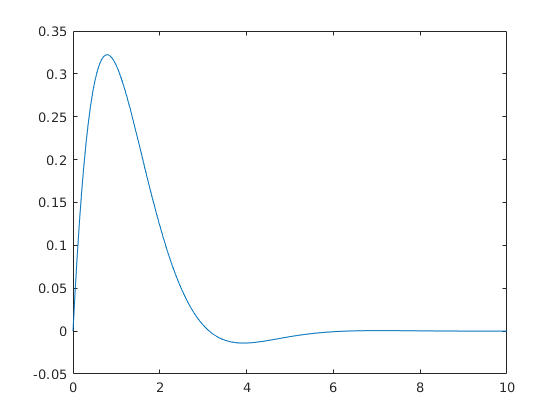

t = linspace(0,10,200);
x = (exp(-1*t).*sin(1*t));
Fs = 1/20;
plot(t,x)

### Fourier Transform of Signal

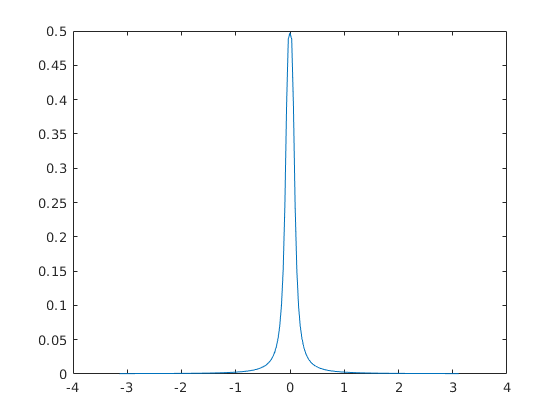

Xw = fft(x);
Ns = size(Xw);
Ns = Ns(2);
w = 2*pi*([-Ns/2:(Ns/2)-1])/Ns;

plot(w,Fs*fftshift(abs(Xw)))

### Laplace Transform of Signal

syms t y
s = (exp(-1*t).*sin(1*t));
Ls = laplace(s);

Ls

$$Ls = \frac{1}{{\left(s+1\right)}^{2}+1}$$

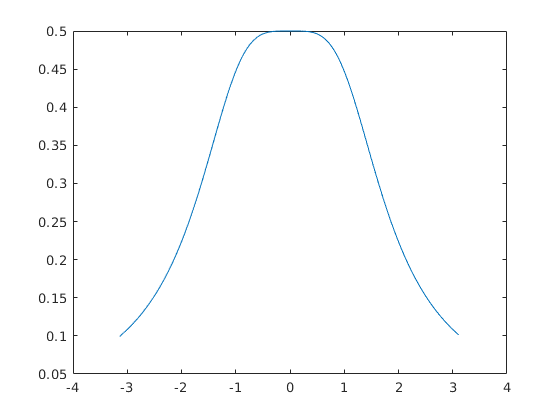

s = 1i*w;
LT = arrayfun(matlabFunction(Ls),s);
plot(w,abs(LT))

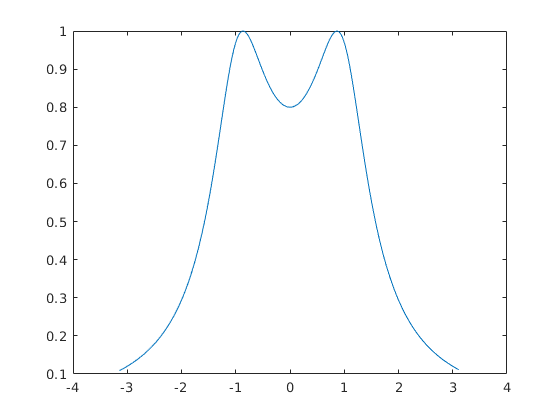

s = -0.5+1i*w;
LT = arrayfun(matlabFunction(Ls),s);
plot(w,abs(LT))  

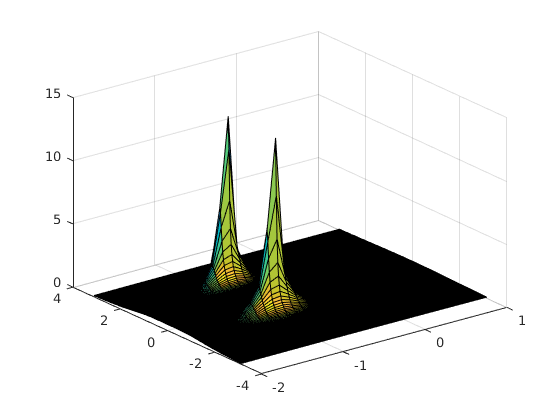

sigma = linspace(-2,1,30);
[X,Y] = meshgrid(sigma,w);
Z = abs(arrayfun(matlabFunction(Ls),X+1j*Y));
surfl(X,Y,Z)

### Undamped Signals

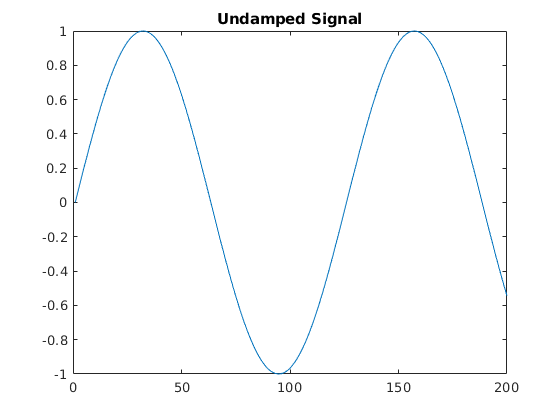

t = linspace(0,10,200);
y = sin(t);
plot(y)
title('Undamped Signal');

syms t Ls
s = sin(t);
Ls = laplace(s);
Ls

$$Ls = \frac{1}{s^{2}+1}$$

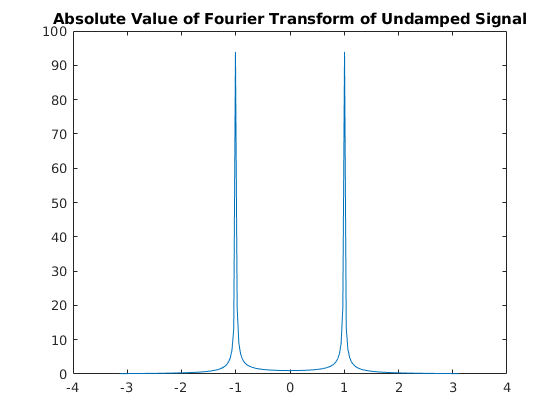

w = 2*pi*([-Ns/2:(Ns/2)-1])/Ns;
s = 1i*w;
LT = arrayfun(matlabFunction(Ls),s);
plot(w,abs(LT))
title('Absolute Value of Fourier Transform of Undamped Signal')

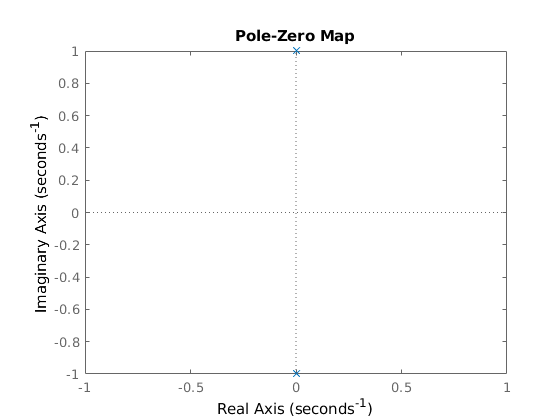

h = pzplot(sym2tf(Ls));

### Underdamped Signals

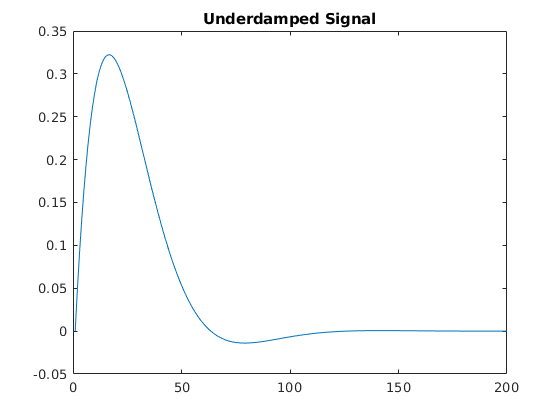

t = linspace(0,10,200);
y = exp(-t).*sin(t);
plot(y)
title('Underdamped Signal')

syms t Ls
s = exp(-t).*sin(t);
Ls = laplace(s);
Ls

$$Ls = \frac{1}{{\left(s+1\right)}^{2}+1}$$

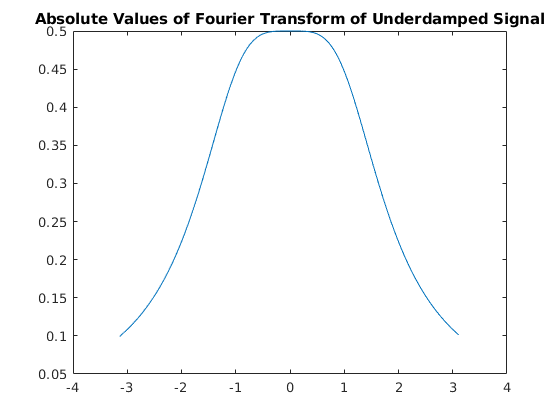

w = 2*pi*([-Ns/2:(Ns/2)-1])/Ns;
s = 1i*w;
LT = arrayfun(matlabFunction(Ls),s);
plot(w,abs(LT)) 
title('Absolute Values of Fourier Transform of Underdamped Signal')

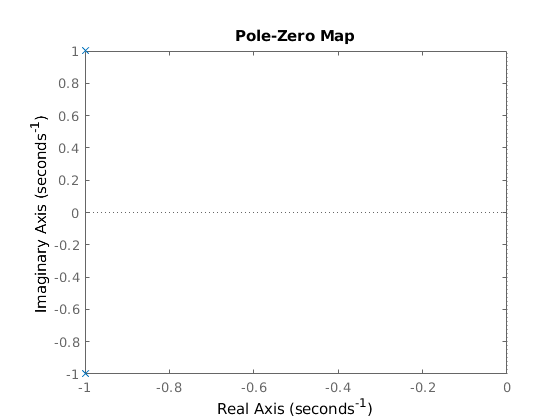

h = pzplot(sym2tf(Ls));

### Critically Damped Signals

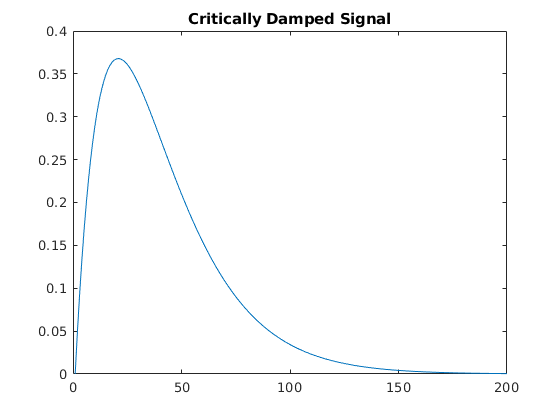

t = linspace(0,10,200);
y = (t).*exp(-t);
plot(y)
title('Critically Damped Signal')

syms t Ls
s = (t).*exp(-t);
Ls = laplace(s);
Ls

$$Ls = \frac{1}{{\left(s+1\right)}^{2}}$$

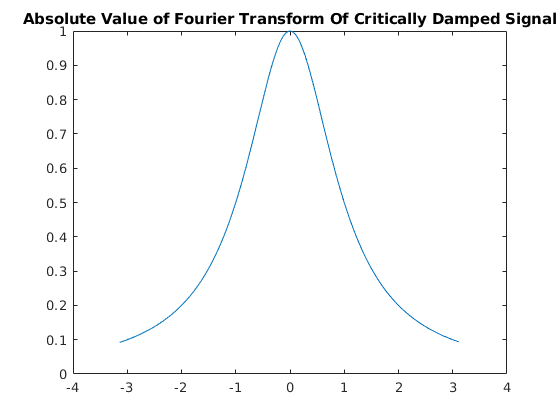

w = 2*pi*([-Ns/2:(Ns/2)-1])/Ns;
s = 1i*w;
LT = arrayfun(matlabFunction(Ls),s);
plot(w,abs(LT))
title('Absolute Value of Fourier Transform Of Critically Damped Signal')

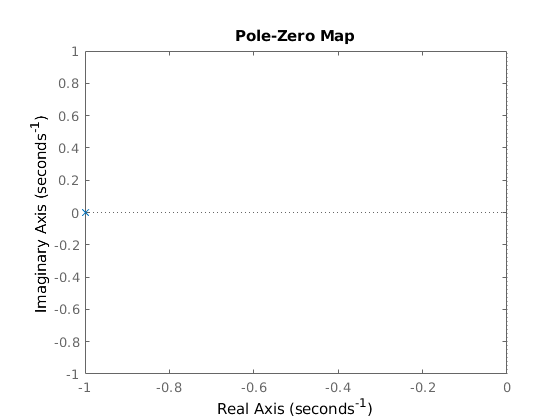

h = pzplot(sym2tf(Ls));

### Overdamped Signals

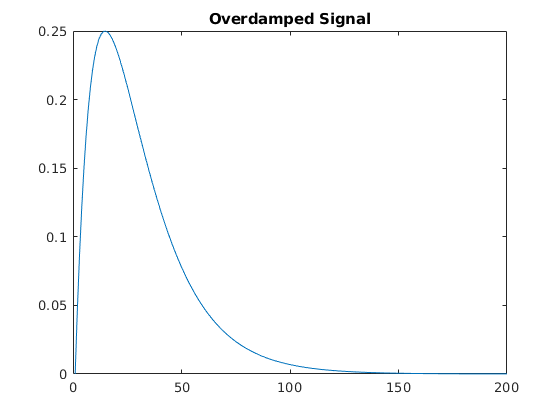

t = linspace(0,10,200);
y = exp(-t) - exp(-2*t);
plot(y)
title('Overdamped Signal')

syms t Ls
s = exp(-t) - exp(-2*t);
Ls = laplace(s);

Ls

$$Ls = \frac{1}{s+1}-\frac{1}{s+2}$$

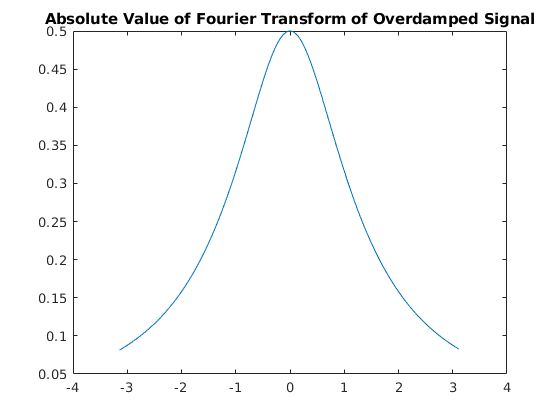

w = 2*pi*([-Ns/2:(Ns/2)-1])/Ns;
s = 1i*w;
LT = arrayfun(matlabFunction(Ls),s);
plot(w,abs(LT))
title('Absolute Value of Fourier Transform of Overdamped Signal')

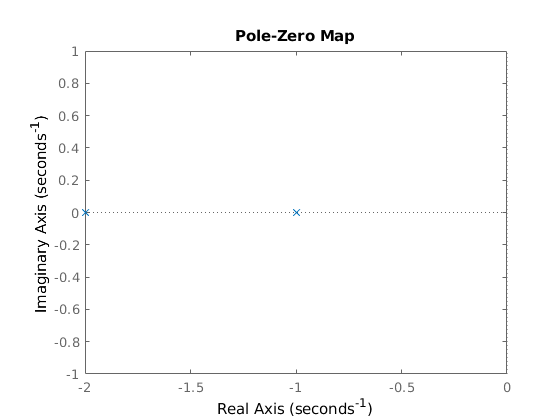

h = pzplot(sym2tf(Ls));

### Function to convert System Function to tf -----> Matlab Formats

function G = sym2tf(g)
[n,m]=size(g);
for i=1:n
    for j=1:m
        [num,den]=numden(g(i,j));
        num_n=sym2poly(num);
        den_n=sym2poly(den);
        G(i,j)=tf(num_n,den_n);
    end
end
end